# MMSE channel estimation

## 1 Perpare data

We create some OFDM data

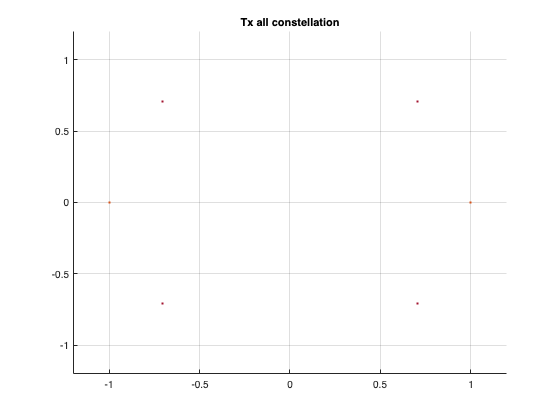

close all

generate_demo_OFDM2;

cSNR = 20;

## 2 channel model

We chose 

## 3 LS estimation

### 3.1 without noise LS estimation

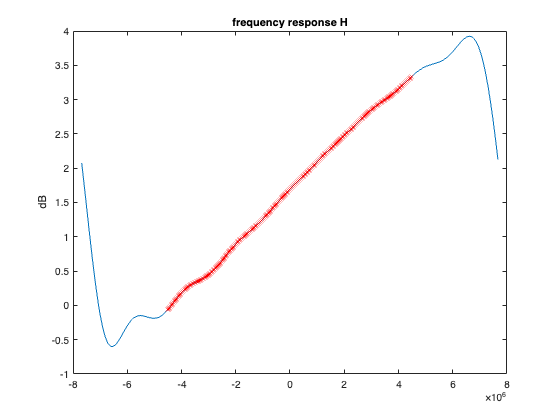

[rx, H] = help_rayleigh(tm, nfft, fs);


% demod
freq = azcomm.ofdmdemod(rx, repmat(cp_len, nsym, 1), nfft, nsc_all);

H_hat_LS = channel_est_LS(freq, grids, (1:nsc_all), idx_preamble_sym);

figure;
help_plot_frequency_response(H, H_hat_LS, fs);

fprintf("MSE of LS without noise: %f\n", help_MSE(H, H_hat_LS));

MSE of LS without noise: 0.000000


We can find that, LS can fitting good without noise.

### 3.2 with noise

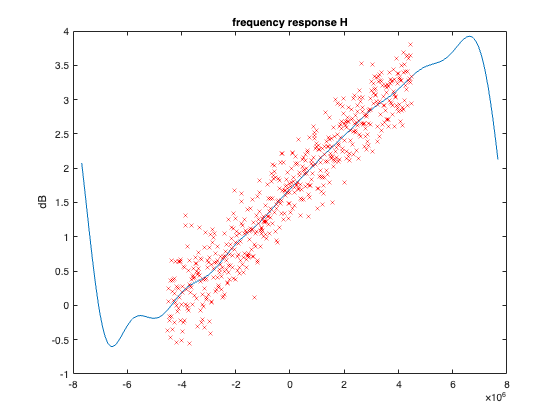

[rx, H] = help_rayleigh(tm, nfft, fs);
rx = awgn(rx, cSNR, 'measured');

% demod
freq = azcomm.ofdmdemod(rx, repmat(cp_len, nsym, 1), nfft, nsc_all);

H_hat_LS = channel_est_LS(freq, grids, (1:nsc_all), idx_preamble_sym);

figure;
help_plot_frequency_response(H, H_hat_LS, fs);

fprintf("MSE of LS with noise: %f\n", help_MSE(H, H_hat_LS));

MSE of LS with noise: 0.004226


## 4 MMSE estimation

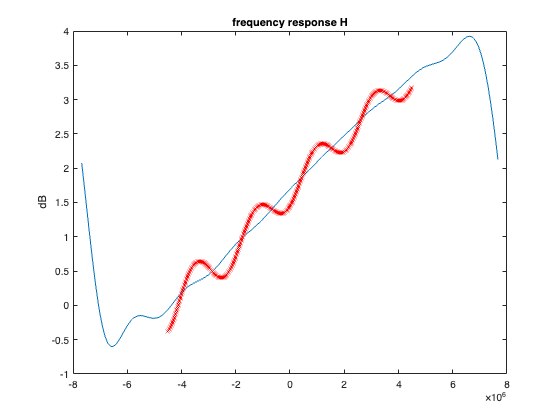

snr_linear = 10 ^ (cSNR/10);
sigma_2 = 1 / snr_linear;
H_part = fftshift(H);
H_part = H_part((nfft-nsc_all)/2+1:(nfft-nsc_all)/2+nsc_all);
H_norm = H_part - mean(H_part);
RHH = H_norm * H_norm';
X = diag(grids(:, 1));  % diag is import
H_Hat_MMSE = RHH * inv(RHH + sigma_2*inv(X*X'))*H_hat_LS;
figure;
help_plot_frequency_response(H, H_Hat_MMSE, fs);

fprintf("MSE of MMSE with noise: %f\n", help_MSE(H, H_Hat_MMSE));

MSE of MMSE with noise: 0.001256


## 5 EVM

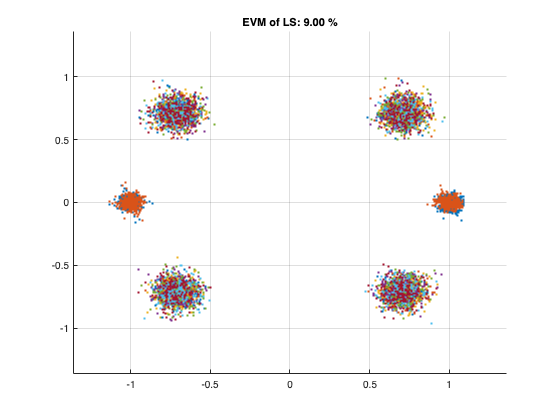

equ_LS = freq ./ repmat(H_hat_LS, 1, size(freq, 2));
equ_MMSE = freq ./ repmat(H_Hat_MMSE, 1, size(freq, 2));

evmer = comm.EVM;
evm_ls = evmer(equ_LS, grids);

release(evmer);
evm_MMSE = evmer(equ_MMSE, grids);

figure;
plot_scatterIQ(equ_LS);
title(sprintf('EVM of LS: %.2f %%', mean(evm_ls)));

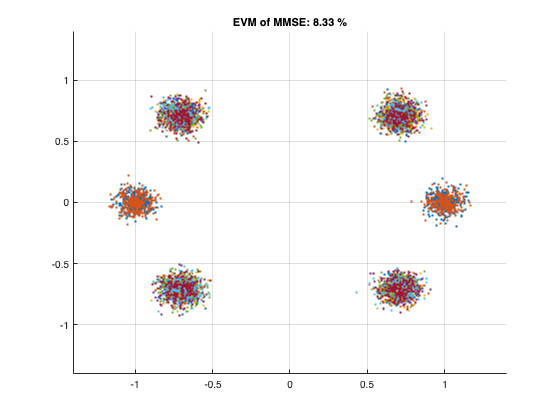

figure;
plot_scatterIQ(equ_MMSE);
title(sprintf('EVM of MMSE: %.2f %%', mean(evm_MMSE)));

function [rx, H] = help_rayleigh(tx, nfft, fs)
    pathDelays = [0 10 20 30 ]*1e-9; % in seconds
    avgPathGains0 = [0 -3 -10 -8 ]; % dB
    
    fD = 0; % Max Doppler shift in Hz
    rayleigh = comm.RayleighChannel('SampleRate',fs, ...
            'PathDelays' ,pathDelays,...
            'AveragePathGains',avgPathGains0,...
            'MaximumDopplerShift',fD, ...
            'RandomStream','mt19937ar with seed', ...
            'Seed',22, ...  
            'Visualization', 'Off');
    rx = rayleigh(tx);  % get signal through channel
    release(rayleigh);
    rayleigh.RandomStream = 'Global stream';
    rng(22);
    
    impulse = [1; zeros(nfft-1, 1)];
    h = rayleigh(impulse);  % get the impulse response on the same channel
    H = fft(h);
end

function [] = help_plot_frequency_response(H, Hest, fs)
    nfft = length(H);
    nsc_all = size(Hest, 1);
    fax = (-nfft/2:nfft/2-1) * (fs / nfft);
    plot(fax, mag2db(abs(fftshift(H)))); hold on;
    ylabel('dB')
    title('frequency response H')

    % plot estimate by LS
    plot(fax((nfft-nsc_all)/2+1:(nfft-nsc_all)/2+nsc_all), mag2db(abs(Hest)), 'rx');
end

function [m] = help_MSE(H, Hest)
    nfft = length(H);
    nsc_all = size(Hest, 1);
    Hs = fftshift(H);
    Href = Hs((nfft-nsc_all)/2+1:(nfft-nsc_all)/2+nsc_all);

    m = mean(abs(Href-Hest).^2);
end

function [H] = channel_est_LS(rx_grid, raw_grid, rs_k, rs_sym)
    N_sym = size(rx_grid,2);
    H = rx_grid(rs_k, rs_sym) ./ raw_grid(rs_k, rs_sym);

    H = mean(H, 2);
end